**Exercise 1**

Suppose you are interested in the speed of cars passing by a certain point on a certain road within a specific hour. To get information about that, you are measuring the speed of 3 cars passing by during that hour. Identify the variable, population and sample.

In the above example the variable would be the speed of the cars, the population is all the cars passing by a certain point on a road within a specified hour and the smple is the three cars whose speed you are measuring. 

**Exercise 2**

For ceiling fans to rotate effectively, the bending angle of the individual paddles of the fan must remain between tight limits. Each fan has two paddles. From a monthly production (in some company), 25 fans are selected and the angles are measured. The purpose of the investigation is to find out about fans working properly or not. Identify the variable, population, and sample.

In the above example, the variable is the bending angle of the paddles, the population is all the paddles on all fans produced that month and the sample is the paddles of the 25 fans. 

**Exercise 3**

Consider the data set `DensityEarth.txt`. This data set contains 29 measurements of the density of the earth, given as a multiple of the density of water. Use MATLAB (or what you prefer) to construct a histogram with 10 classes and a histogram with 4 classes. The relevant function for MATLAB is `hist()`.

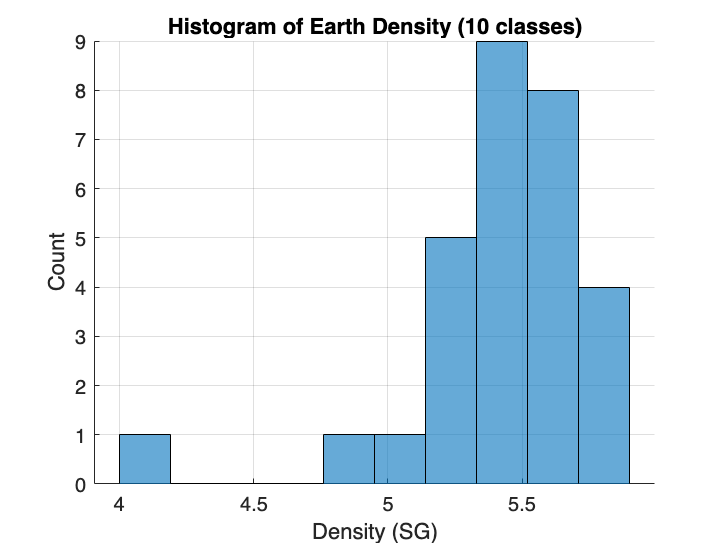

clear; clc; close all;

densityData = importdata('./data/DensityEarth.txt');

figure('Name','Density of Earth - 10 Classes');
hold on;
histogram(densityData, 10);
grid on;
xlabel('Density (SG)');
ylabel('Count');
title('Histogram of Earth Density (10 classes)');

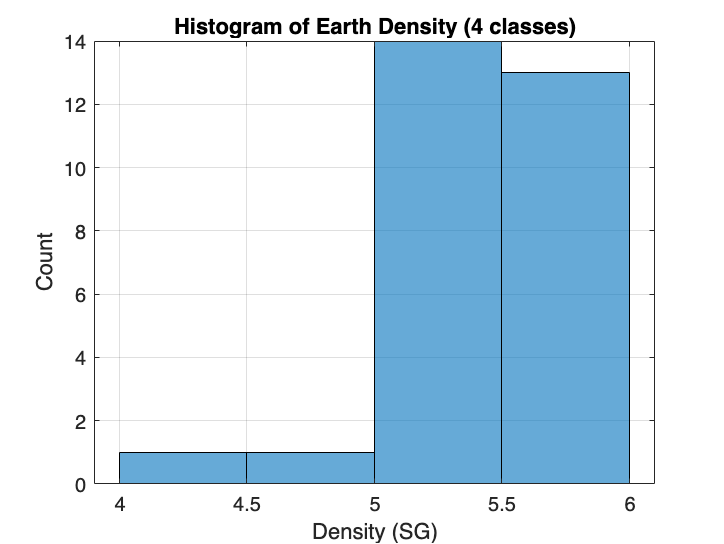


figure('Name','Density of Earth - 4 Classes');
histogram(densityData, 4);
grid on;
xlabel('Density (SG)');
ylabel('Count');
title('Histogram of Earth Density (4 classes)');

hold off;

**Exercise 4**

Consider the data set `fish.txt`, containing 14 observations of the prices in cents per pound for several species of fish in 1970 and 1980. Use MATLAB (or what you prefer) to construct a histogram with 14 classes and a histogram with 7 classes for fish prices in 1970. The relevant function for MATLAB is `hist()`.

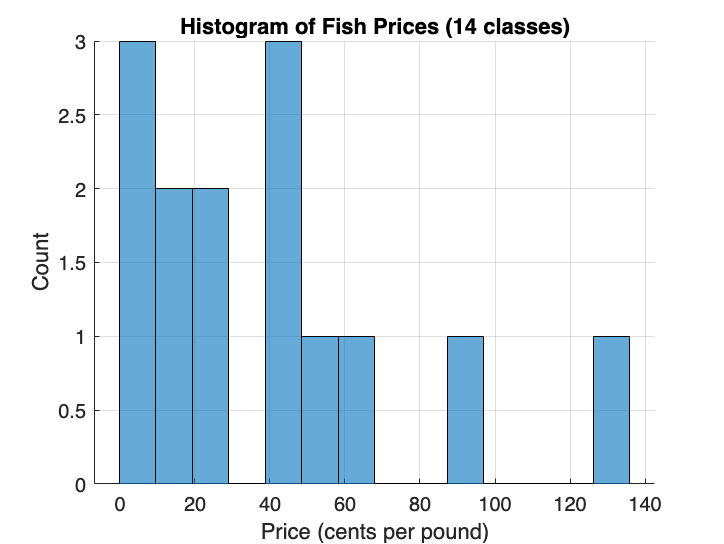

clear; clc; close all;

priceData = importdata('./data/fish.txt');

price1970 = priceData.data(:, 1);

figure('Name','1970 Fish price - 14 Classes');
hold on;
histogram(price1970, 14);
grid on;
xlabel('Price (cents per pound)');
ylabel('Count');
title('Histogram of Fish Prices (14 classes)');

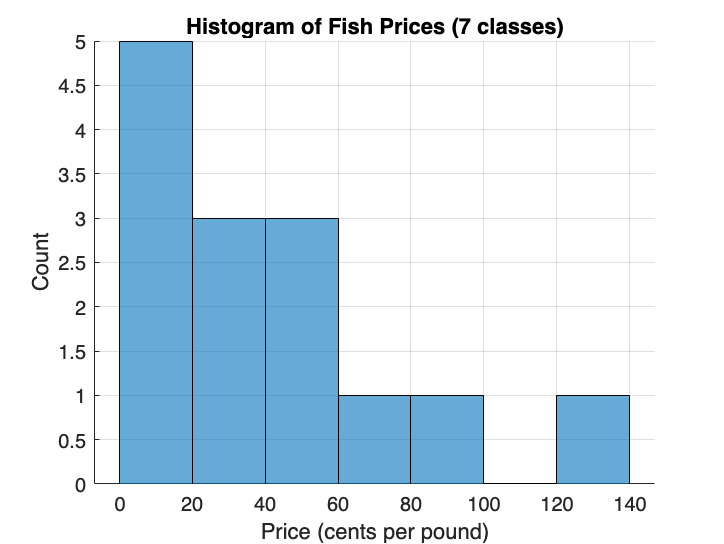


figure('Name','1970 Fish price - 7 Classes');
hold on;
histogram(price1970, 7);
grid on;
xlabel('Price (cents per pound)');
ylabel('Count');
title('Histogram of Fish Prices (7 classes)');

hold off;

**Exercise 5**

Consider the data set `DensityEarth.txt`. Use MATLAB (or what you prefer) to construct a modified boxplot. The relevant function for MATLAB is `boxplot()`.

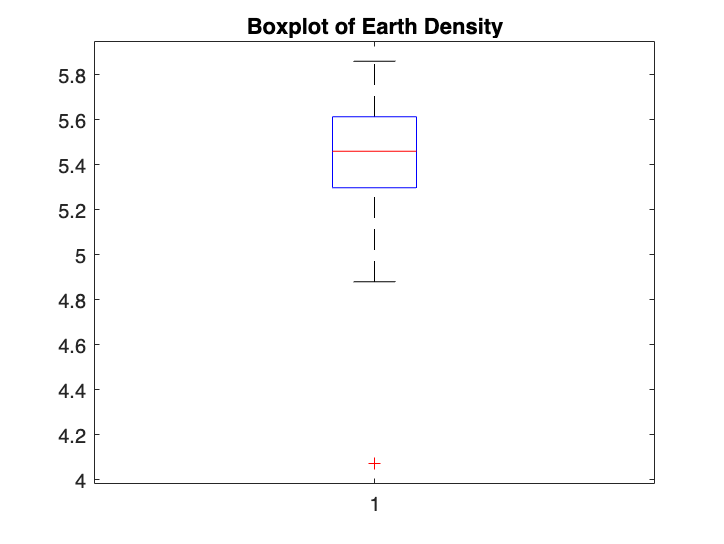

clear; clc; close all;

densityData = importdata('./data/DensityEarth.txt');

boxplot(densityData);
title('Boxplot of Earth Density');

**Exercise 6**

Consider the data set `fish.txt`. Use MATLAB (or what you prefer) to construct a modified boxplot for fish prices in 1970 and in 1980. The relevant function for MATLAB is `boxplot()`. Describe similarities and differences.

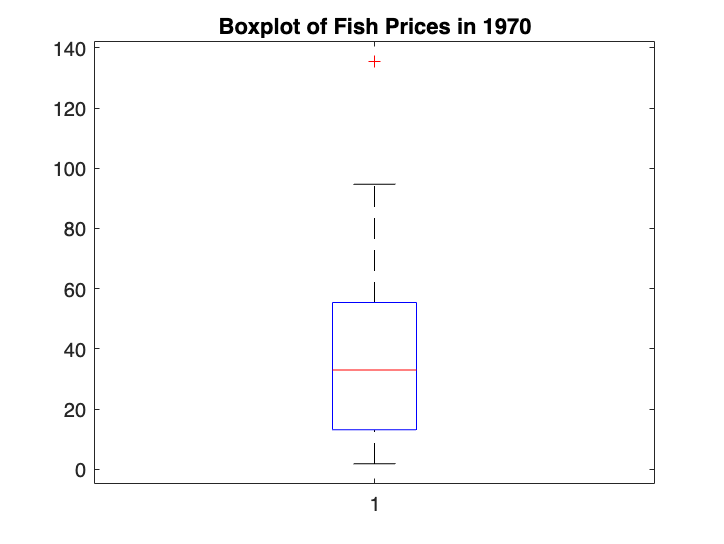

clear; clc; close all;

priceData = importdata('./data/fish.txt');

price1970 = priceData.data(:, 1);
price1980 = priceData.data(:, 2);


boxplot(price1970);
title('Boxplot of Fish Prices in 1970');

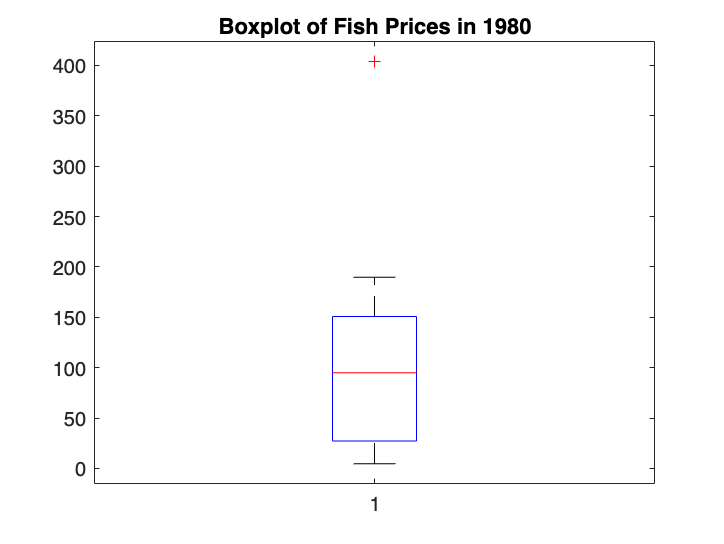


boxplot(price1980);
title('Boxplot of Fish Prices in 1980');

Similar for both boxplots is the singular outlier with a high price. Further, for both boxplots the data in the interquartile range is approximately symmetrical around the median. 

However, it seems as if fish prices in general rose quite a bit over the period and the data in 1980 has a lower spread of the non-outlier data.

**Exercise 7**

Consider a sample $x_1, \ldots, x_n$ of size $n > 1$. Show that


$$\sum_{i = 1}^n (x_i - \overline{x} ) = 0$$


We start with


$$\sum_{i=1}^n (x_i - \overline{x}) = \sum_{i = 1}^n x_i - \sum_{i = 1}^n \overline{x} = n\frac{1}{n} \sum_{i = 1}^n x_i - n \overline{x}$$


We now use the fact that


$$\sum_{i = 1}^n \overline{x} = \frac{1}{n} \sum_{i = 1}^n x_i$$


And get


$$n \overline{x} - n \overline{x} = 0$$


**Exercise 8**

Consider a sample $x_1, \ldots, x_n$ of size $n > 1$. Show that


$$s^2 = \frac{1}{n-1} \sum_{i  =1}^n x_i^2 - \frac{n}{n-1} \overline{x}^2$$


We remember that


$$s^2 = \frac{1}{n-1} \sum_{i = 1}^{n} \left( x_i - \overline{x} \right)^2$$


We now expand the parenthesis as:


$$s^2 = \frac{1}{n-1} \left( \sum_{i = 1}^{n} x_i^2 - 2 \sum_{i = 1}^{n} x_i \overline{x} + \sum_{i = 1}^{n} \overline{x}^2 \right)$$


We now expand the sums with $\overline{x}$ as


$$s^2 = \frac{1}{n-1} \left( \sum_{i = 1}^{n} x_i^2 - 2 \overline{x} \sum_{i = 1}^{n} x_i + n \overline{x}^2 \right)$$


Using algebra we now get


$$s^2 = \frac{1}{n-1} \left( \sum_{i = 1}^{n} x_i^2 - 2 \overline{x} n \overline{x} + n \overline{x}^2 \right)$$



$$s^2 = \frac{1}{n-1} \sum_{i  =1}^n x_i^2 - \frac{n}{n-1} \overline{x}^2$$
